clear
clf
G = imread('fish.png')

G = 552×860×3 uint8 array
G(:,:,1) =

   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247  

whos G

  Name        Size                 Bytes  Class    Attributes

  G         552x860x3            1424160  uint8              



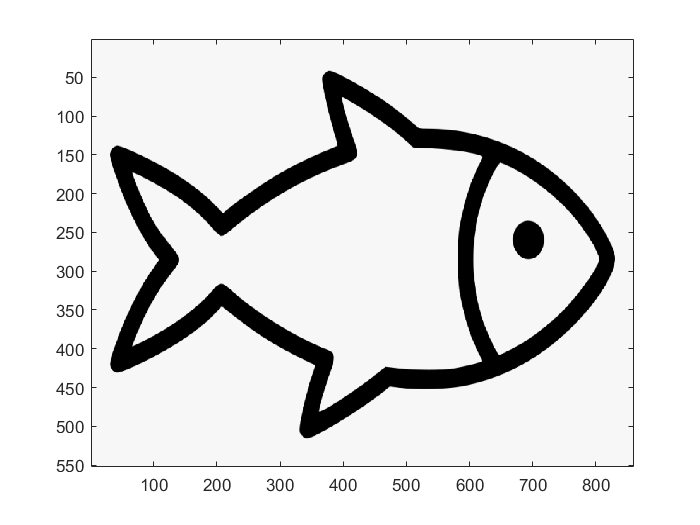

image(G)

GrayG = rgb2gray(G)

GrayG = 552×860 uint8 matrix
   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   247   247   247  

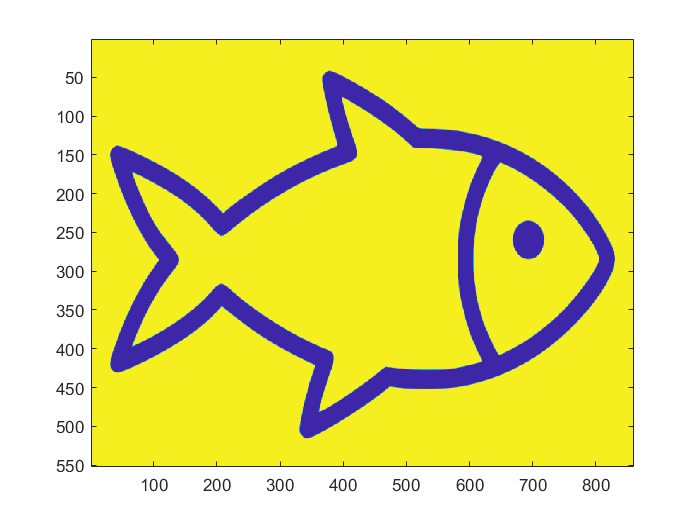

image(GrayG)

dim = 22

dim = 22

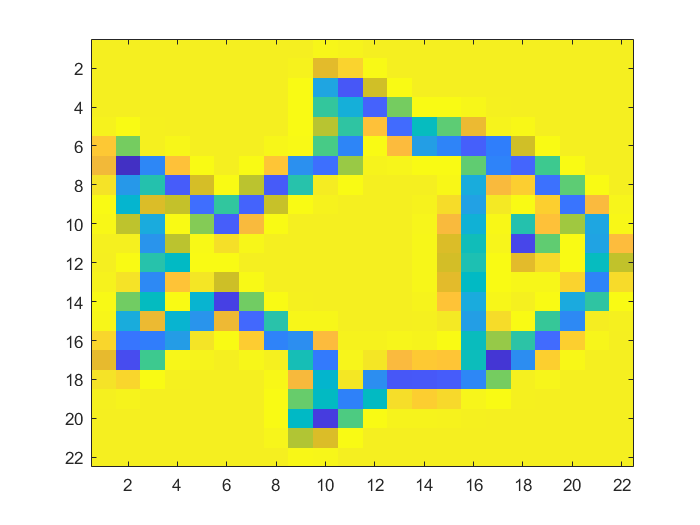

grayresize = imresize(GrayG,[dim dim]);
image(grayresize)

grayresize

grayresize = 22×22 uint8 matrix
   247   247   247   247   247   247   247   247   247   252   250   247   247   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   249   201   229   254   247   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   255    98    40   194   255   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   255   143   107    48   167   255   255   252   248   247   247   247   247   247
   249   255   248   247   247   247   247   247   255   186   140   217    54   124   160   205   250   253   247   247   247   247
   222   167   248   252   247   247   247   252   254   153    72   255   213    92    71    46    67   194   255   247   247   247
   208    10    73   217   255   247   255   220    80    57   177   250   251   255   255   161    70    50   149   255   247   247
   239    87   134    44   196   255 

Gstacked = grayresize

Gstacked = 22×22 uint8 matrix
   247   247   247   247   247   247   247   247   247   252   250   247   247   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   249   201   229   254   247   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   255    98    40   194   255   247   247   247   247   247   247   247   247   247
   247   247   247   247   247   247   247   247   255   143   107    48   167   255   255   252   248   247   247   247   247   247
   249   255   248   247   247   247   247   247   255   186   140   217    54   124   160   205   250   253   247   247   247   247
   222   167   248   252   247   247   247   252   254   153    72   255   213    92    71    46    67   194   255   247   247   247
   208    10    73   217   255   247   255   220    80    57   177   250   251   255   255   161    70    50   149   255   247   247
   239    87   134    44   196   255   

image(Gstacked)

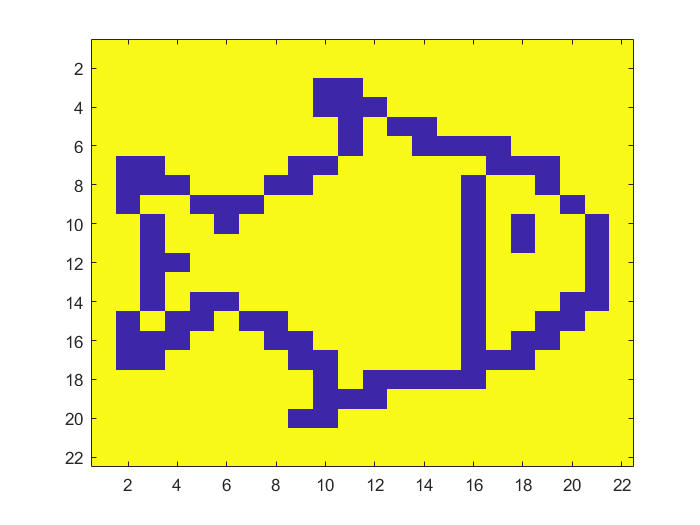


image((Gstacked > 150).*255)


black_and_white = flip((Gstacked > 150).*255)

black_and_white =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255     0     0   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255     0     0     0   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255     0   255     0     0     0     0     0   255   255   255   255   255   255
   255     0     0   255   255   255   255   255     0     0   255   255   255   255   255     0     0     0   255   255   255   255
   255     0     0     0   255   255   255     0     0   255   255   255   255   255   255     0   255     0     0   255   255   255
   255     0   255     0     0   255     0     0   

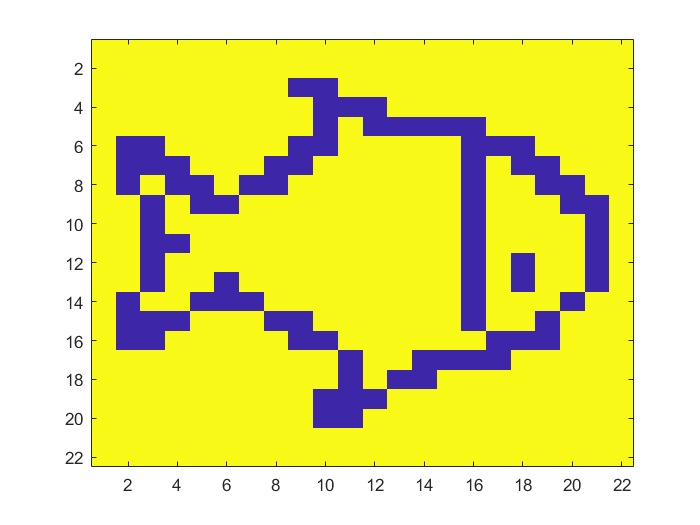


image(black_and_white)


final_vector = zeros(1,dim*dim)

final_vector =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


black_and_white(:,1);

for i = 1:length(black_and_white(:,1))
    final_vector((1+(i-1)*dim:dim+(i-1)*dim)) = black_and_white(:,i)./255;
end


final_vector

final_vector =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     1     1     1     1     1     0     0     0     1     1     1     1     1     1     1     1     1     1     1     0



save('myFile.txt', 'final_vector', '-ASCII','-append');
csvwrite("myfile.csv", final_vector)